## Frequency Demodulation using Differentiator and Envelope Detection

% Clear workspace and close figures
clc;
close all;
clear all;

% Load the audio file
audioFile = 'videoplayback.wav';
[x, fs] = audioread(audioFile);

t = (0:length(x) - 1) / fs; % Time vector

% Split audio into left and right channels
l = x(:, 1); % Left audio
r = x(:, 2); % Right audio

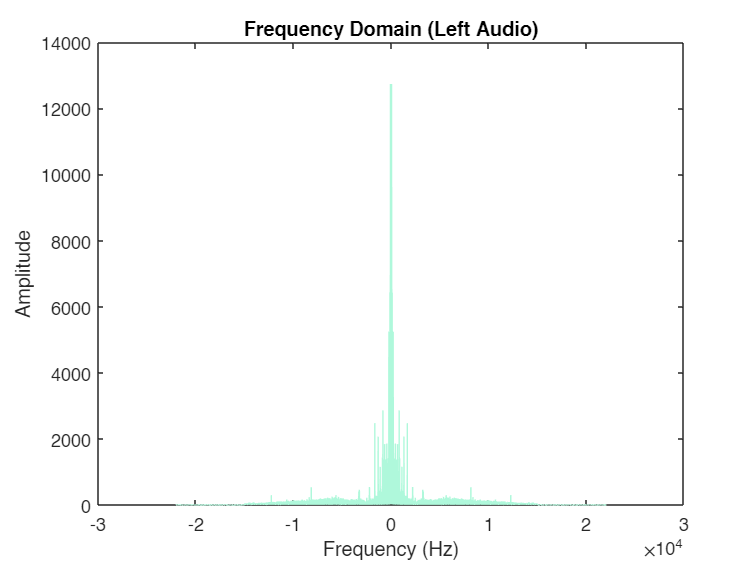

% Plot the original signal in the frequency domain (Left Audio)
L = fft(l);
f = (-length(L)/2:length(L)/2 - 1) * fs / length(L);

figure;
plot(f, abs(fftshift(L)), 'Color', '#aff8db');
title('Frequency Domain (Left Audio)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

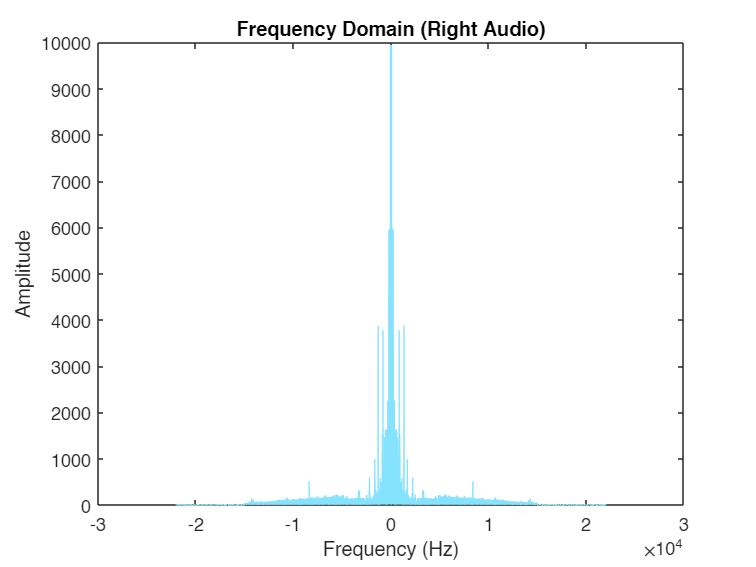


% Plot the original signal in the frequency domain (Right Audio)
R = fft(r);
f = (-length(R)/2:length(R)/2 - 1) * fs / length(R);

figure;
plot(f, abs(fftshift(R)), 'Color', '#85e3ff');
title('Frequency Domain (Right Audio)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

fc = 1e6;

% Carrier Wave
wc = 2 * pi * fc * t;
wc = reshape(wc, size(l));

% Design lowpass filters for left and right channels using butter
[b, a] = butter(5, 8000 / (fs/2), 'low');
 
% Defining modulation indices
mu = [0.5, 1, 2];

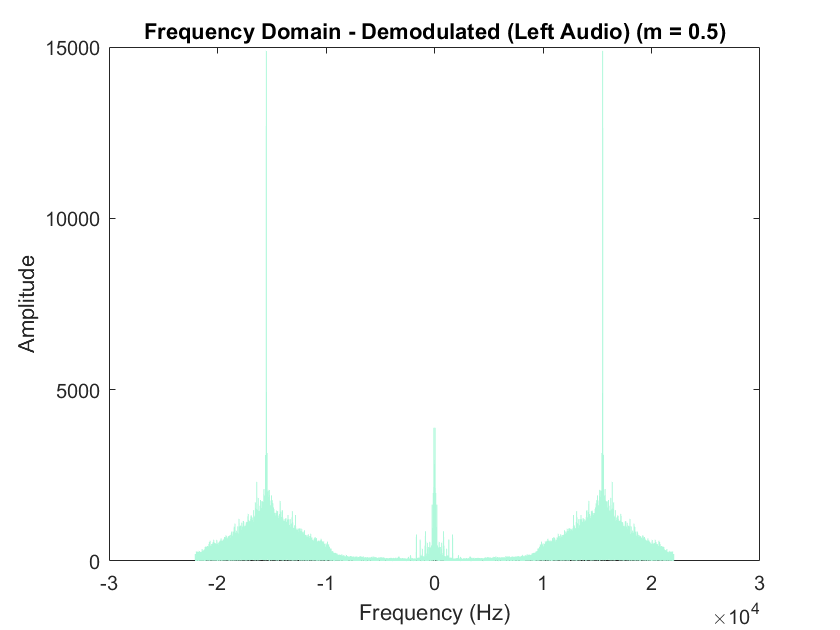

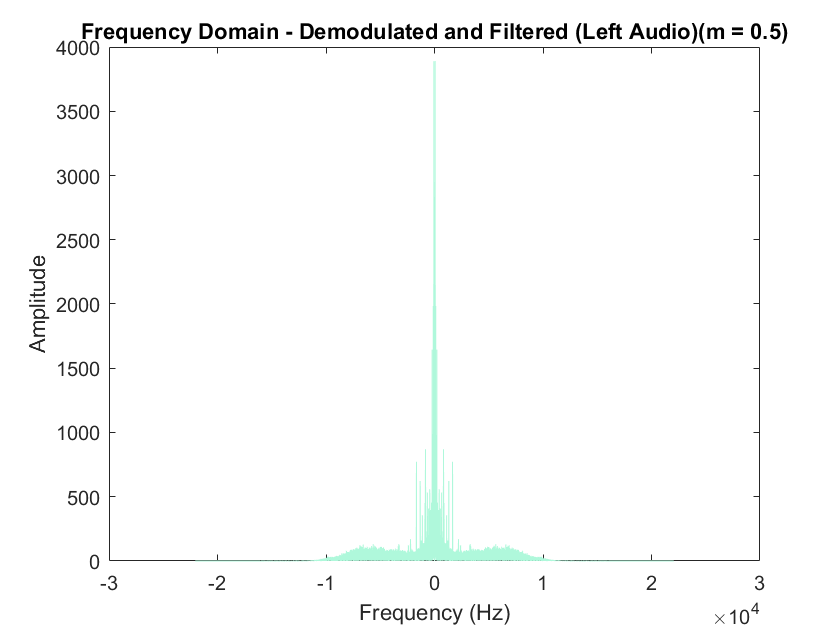

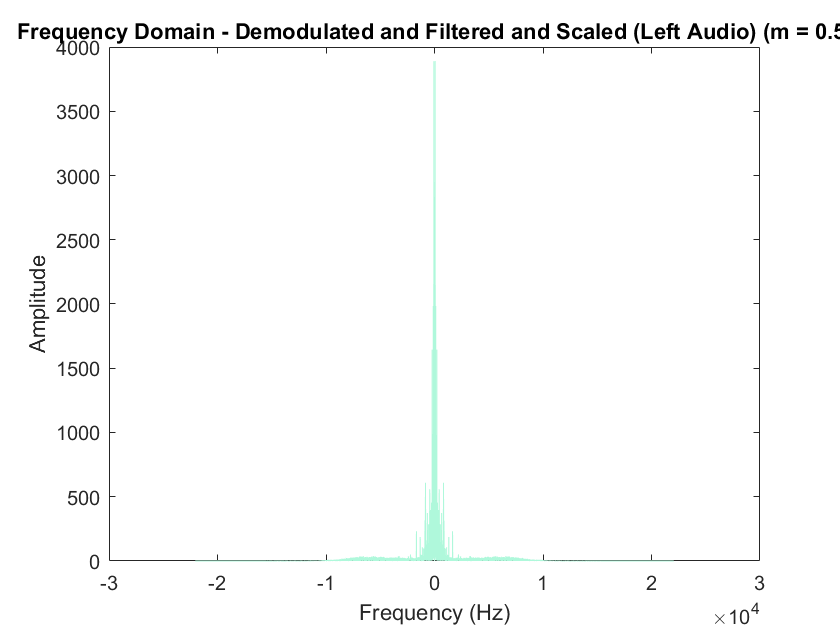

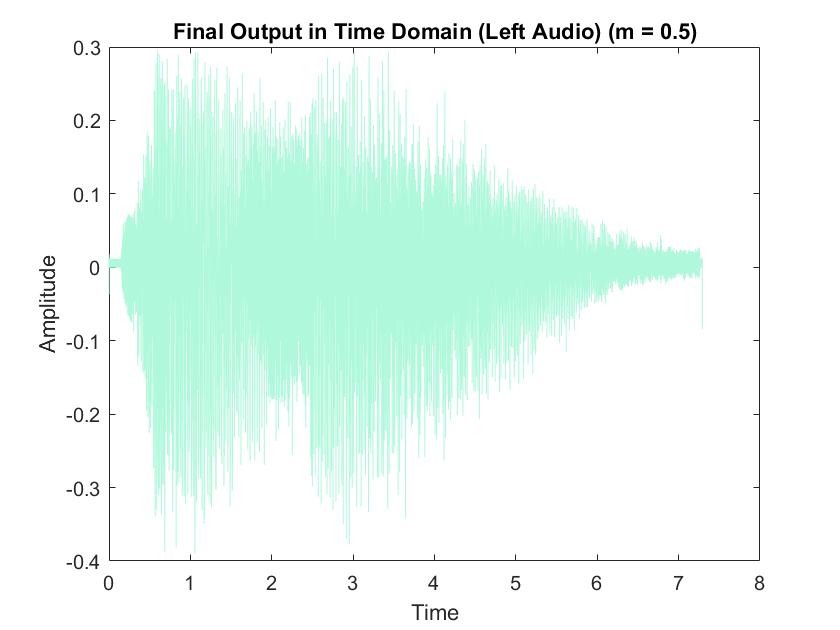

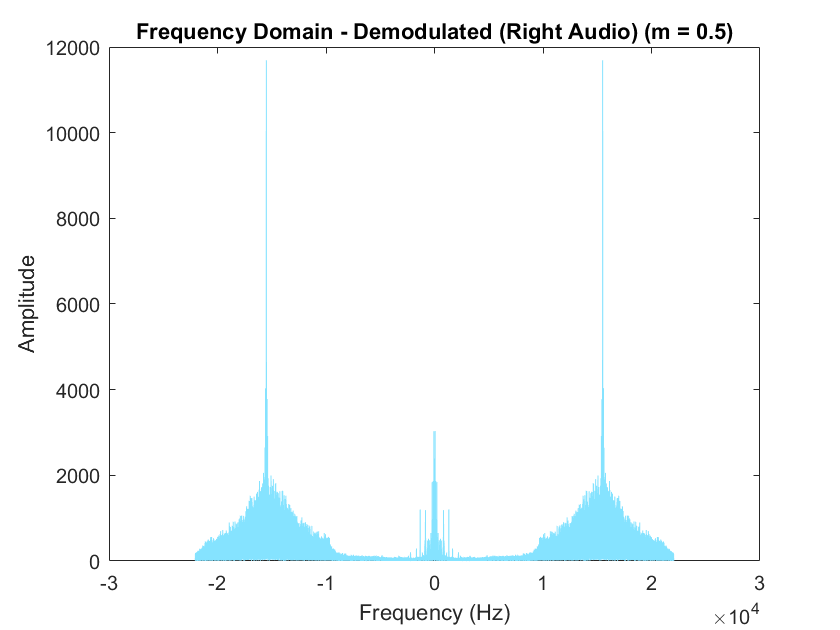

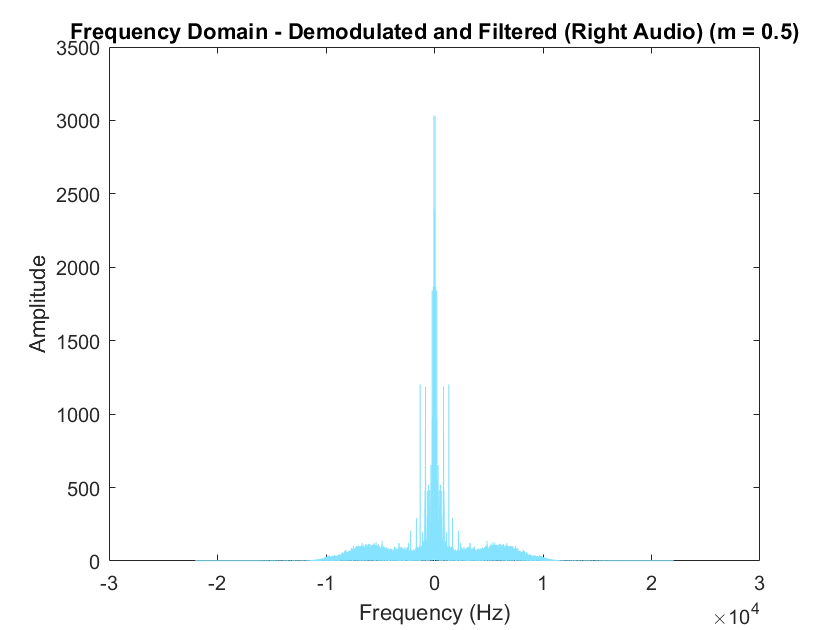

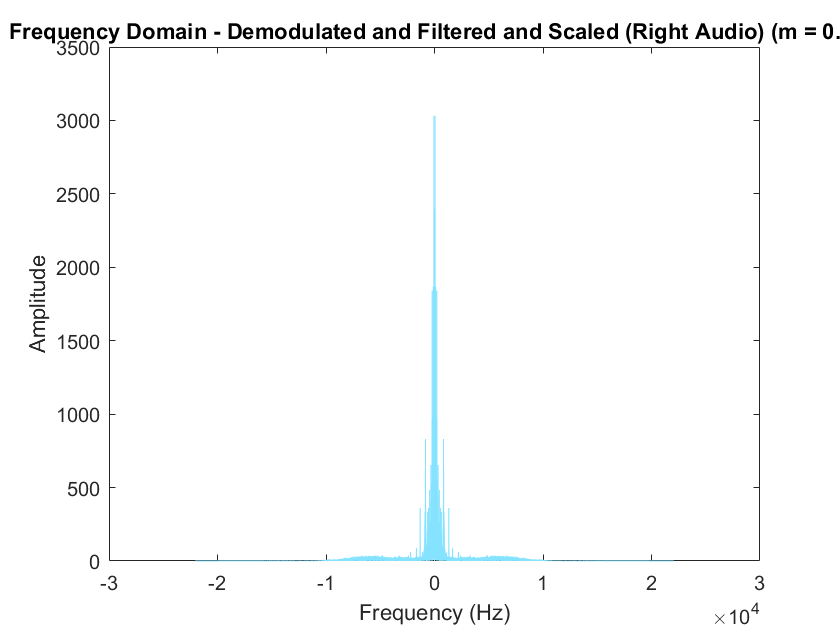

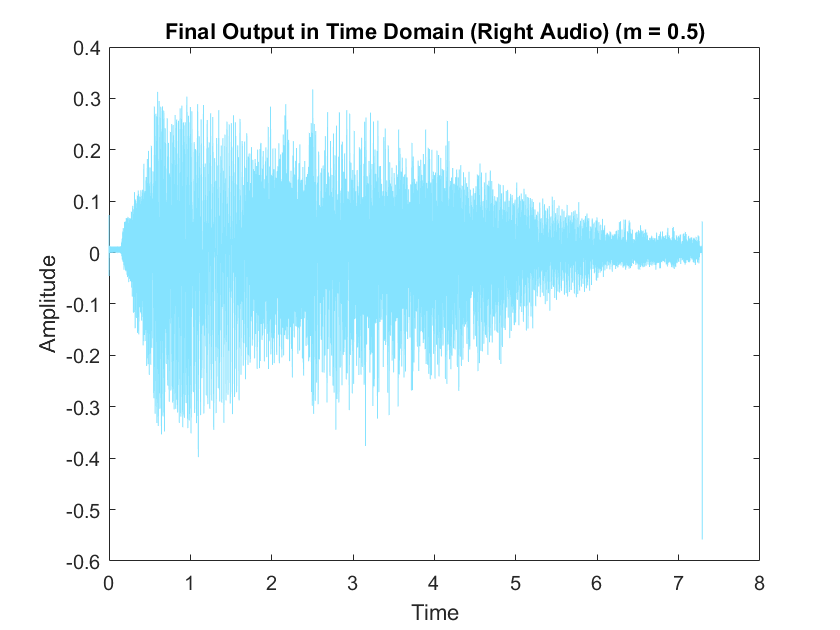

Playing demodulated audio (m = 0.5)


Audio playback completed.


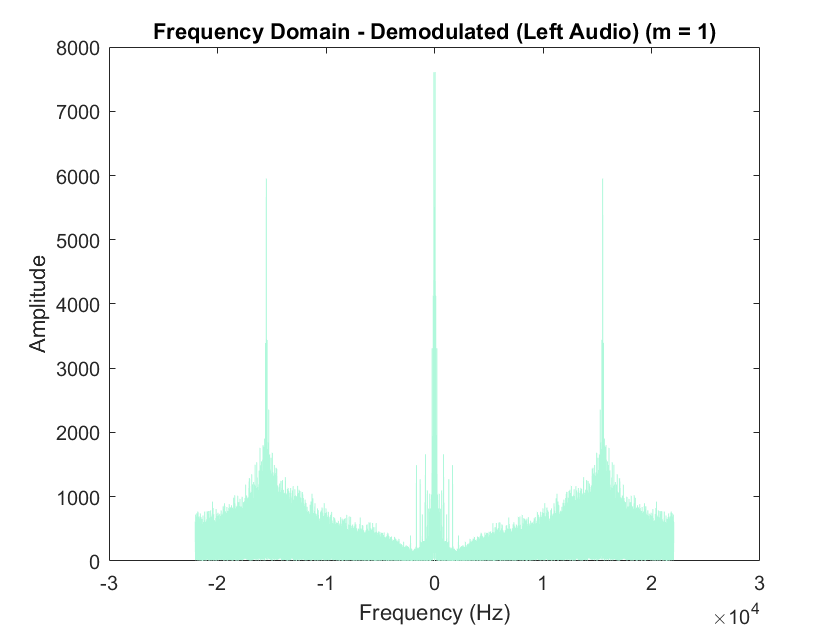

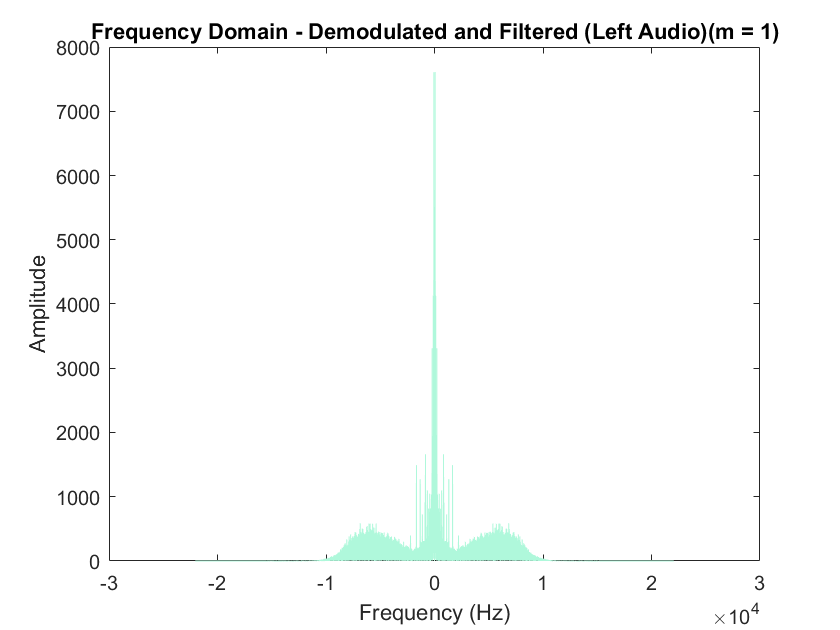

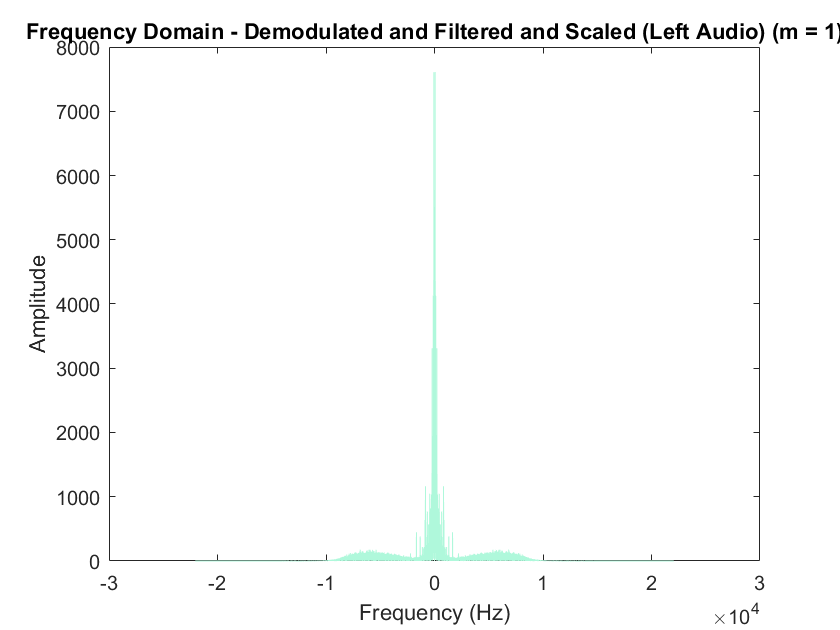

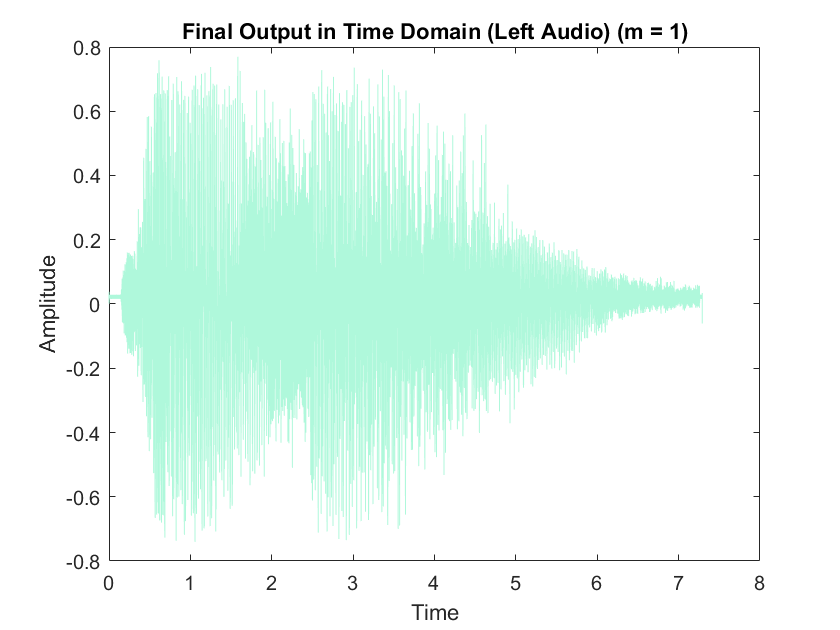

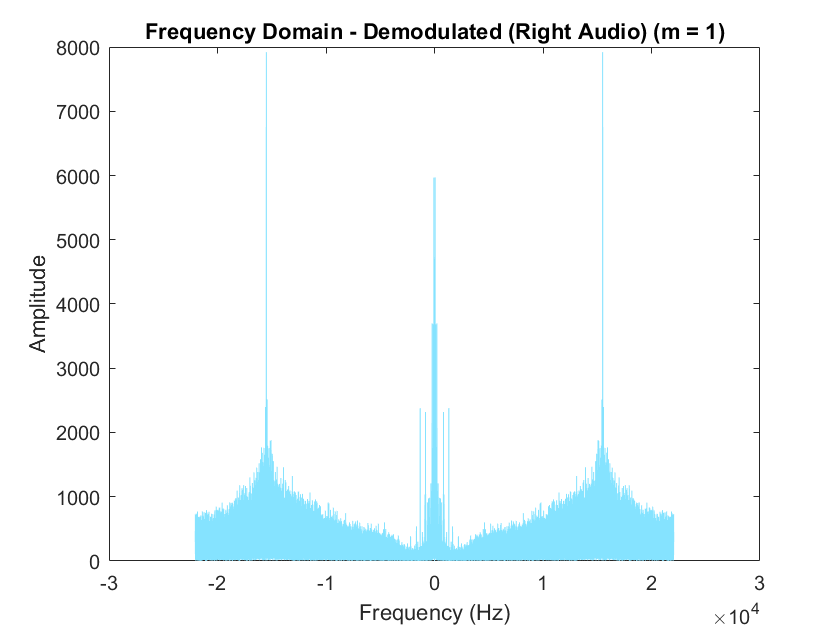

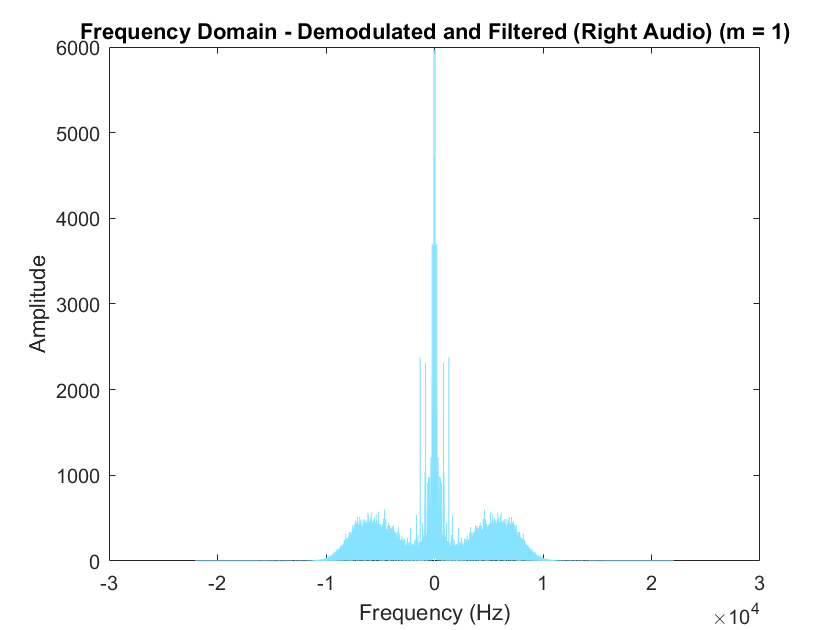

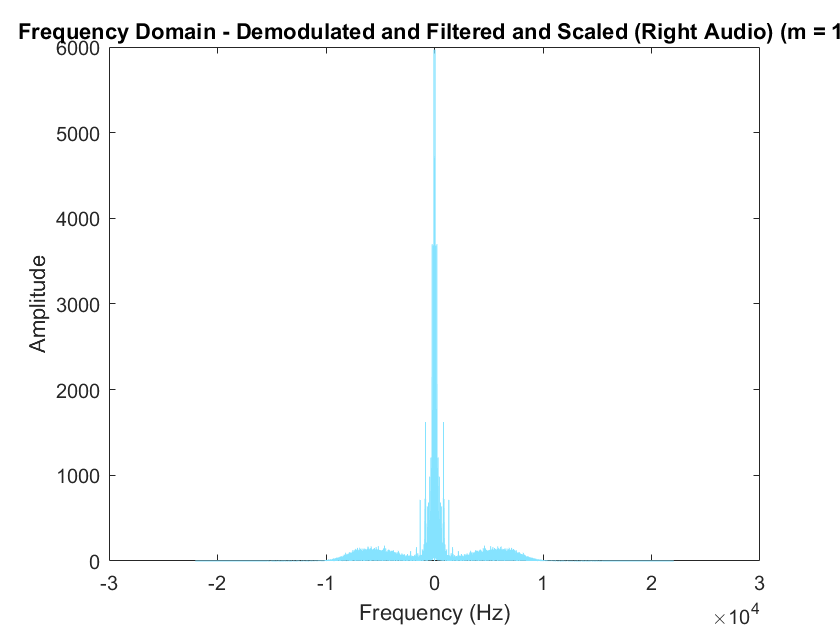

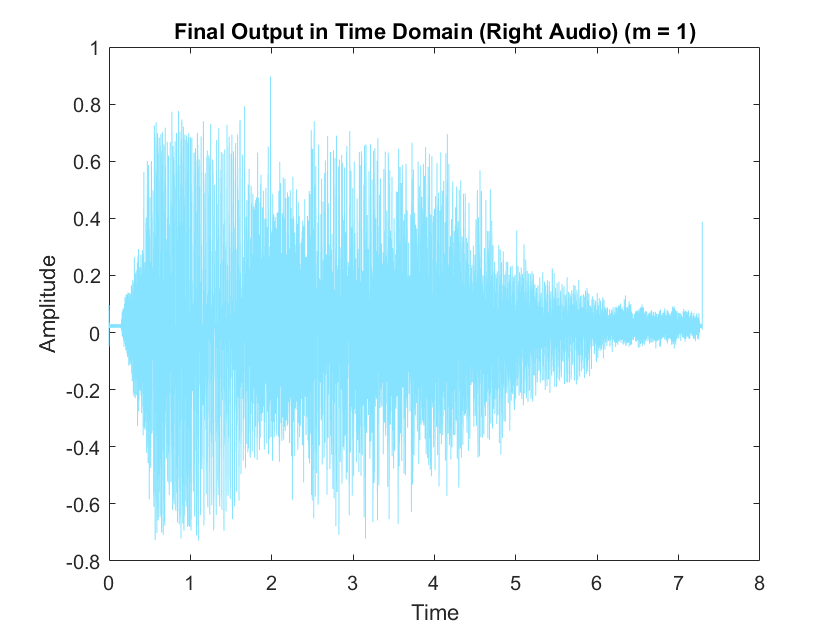

Playing demodulated audio (m = 1)


Audio playback completed.


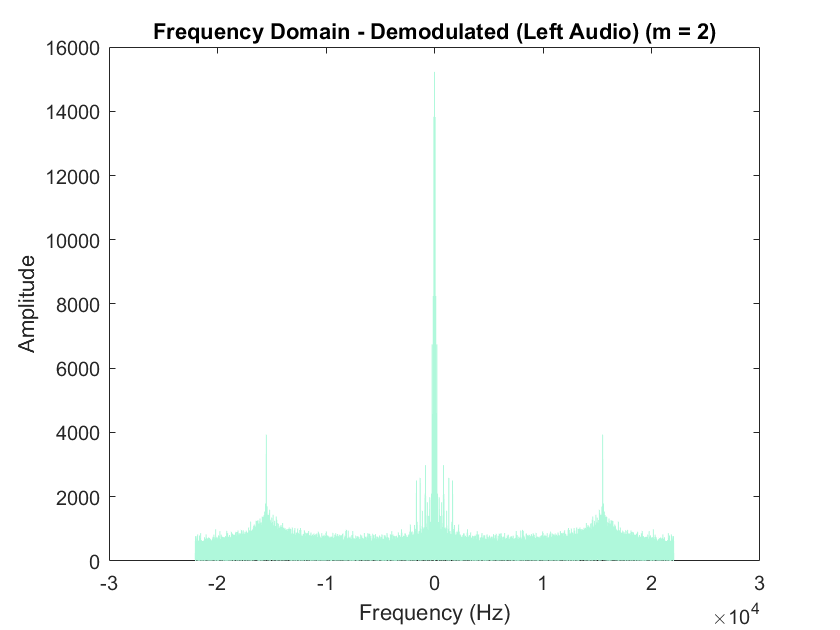

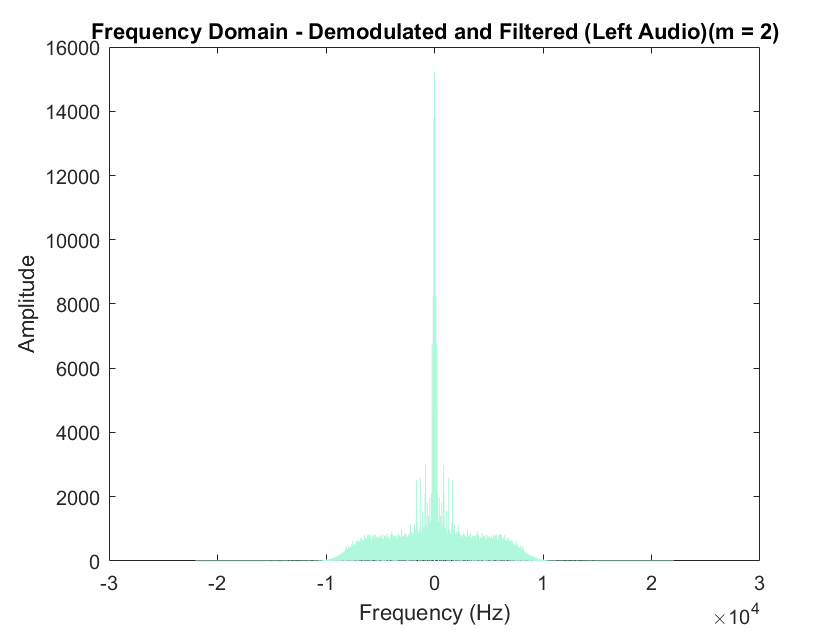

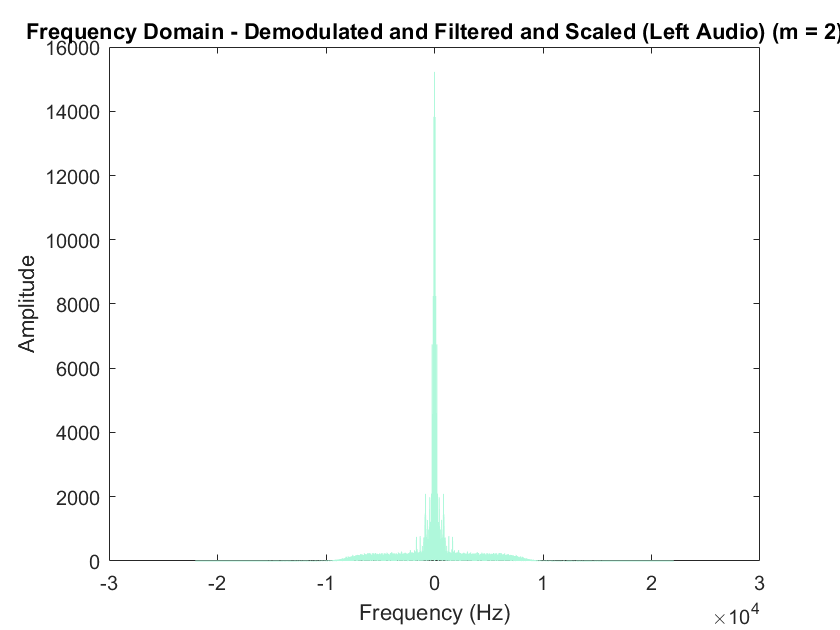

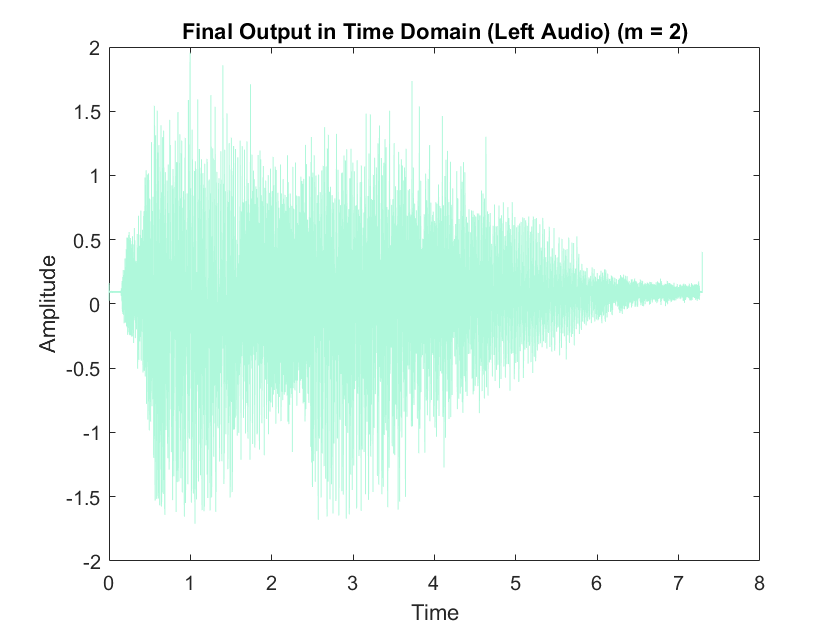

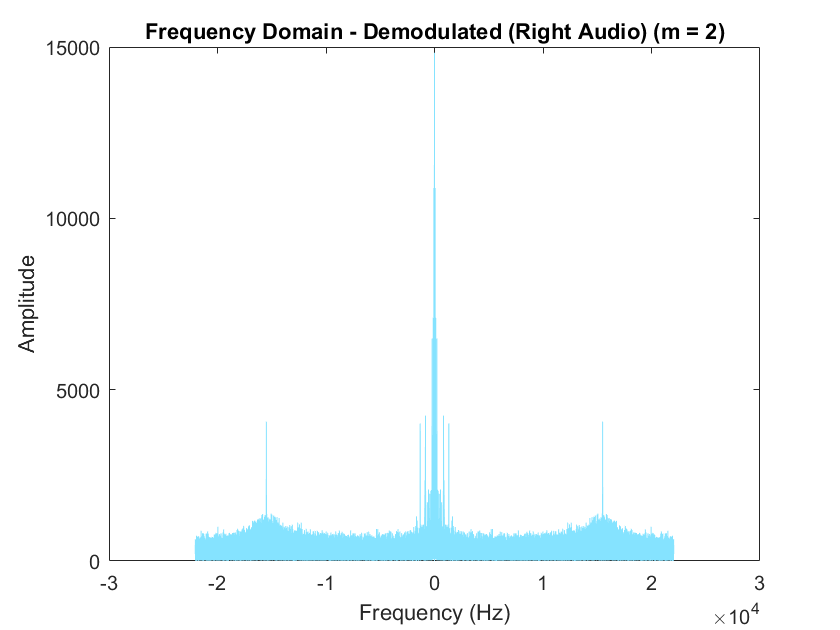

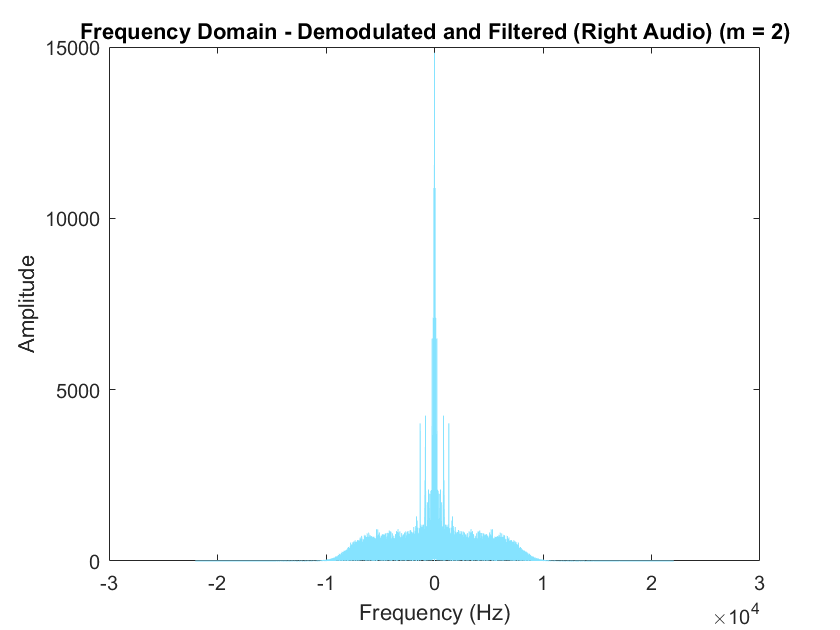

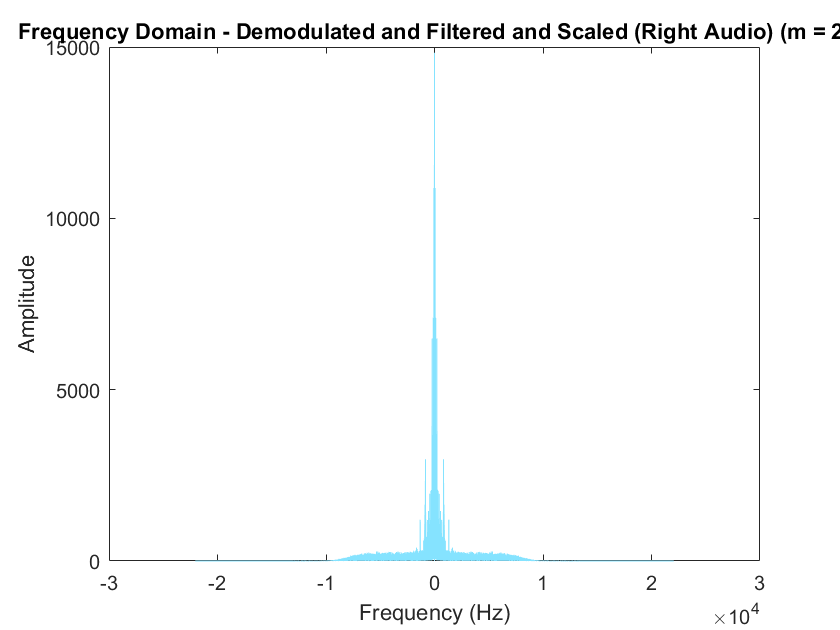

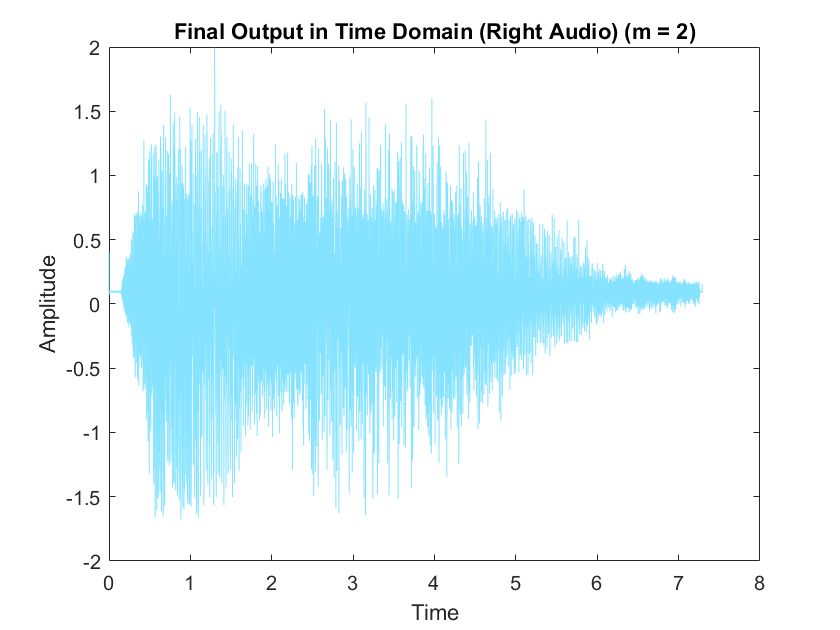

Playing demodulated audio (m = 2)


Audio playback completed.


for i=1:length(mu)

    % Modulating left audio signal    
    left_channel = cos(wc + mu(i) * cumsum(l));
    
    % Modulating right audio signal
    right_channel = cos(wc + mu(i) * cumsum(r)); 

    l_diff = diff(left_channel);
    r_diff = diff(right_channel);

    % Perform incoherent demodulation
    y_demodulated_l = abs(l_diff+ 1i * (hilbert(l_diff)));
    y_demodulated_r = abs(r_diff + 1i * (hilbert(r_diff)));
    
    % Remove DC offset
    y_demodulated_l = y_demodulated_l - mean(y_demodulated_l);
    y_demodulated_r = y_demodulated_r - mean(y_demodulated_r);

    % Apply lowpass filtering to left and right channels using filtfilt
    filtered_left = filtfilt(b, a, y_demodulated_l);
    filtered_right = filtfilt(b, a, y_demodulated_r);

    % Left audio channel
    
    % Plot the demodulated signal in the frequency domain (Left Audio)
    Y_L = fft(y_demodulated_l);
    f = (-length(Y_L)/2:length(Y_L)/2 - 1) * fs / length(Y_L);
    
    figure;
    plot(f, abs(fftshift(Y_L)), 'Color', '#aff8db');
    title(['Frequency Domain - Demodulated (Left Audio) (m = ', num2str(mu(i)), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    
    % Plot the filtered signal in the frequency domain (Left Audio)
    Y_L = fft(filtered_left);
    Y_L = fftshift(Y_L);
    f = (-length(Y_L)/2:length(Y_L)/2 - 1) * fs / length(Y_L);
    
    figure;
    plot(f, abs(Y_L), 'Color', '#aff8db');
    title(['Frequency Domain - Demodulated and Filtered (Left Audio)(m = ', num2str(mu(i)), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    
    % Scaling the signal appropriately
    sc0 = 0;
    sc1 = 0.7;
    sc2 = 0.3;
   
    scale = (abs(f) > 500 & abs(f) <= 1000) * sc1 + (abs(f) > 1000) * sc2 + (abs(f) <= 500) + (abs(f) >= 0 & abs(f) < 10) * sc0;
    scale = reshape(scale, size(Y_L));
    
    Y_L = Y_L .* scale;
    
    % Plotting the spectrum of the scaled signal (Left audio)
    figure;
    plot(f, abs(Y_L), 'Color', '#aff8db');
    title(['Frequency Domain - Demodulated and Filtered and Scaled (Left Audio) (m = ', num2str(mu(i)), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    
    % Perform IFFT
    y_l = ifft(ifftshift(Y_L));
    
    demod = zeros(length(y_l), 2);
    demod(:, 1) = real(y_l);

    % Plot the final processed signal in time domain (Left Audio)
    figure;
    plot(t(1 : length(demod)), demod(:, 1), 'Color', '#aff8db');
    title(['Final Output in Time Domain (Left Audio) (m = ' num2str(mu(i)) ')']);
    xlabel('Time');
    ylabel('Amplitude');
    
    % Right audio channel processing
    
    % Plot the demodulated signal in the frequency domain (Right Audio)
    Y_R = fft(y_demodulated_r);
    f = (-length(Y_R)/2:length(Y_R)/2 - 1) * fs / length(Y_R);
    
    figure;
    plot(f, abs(fftshift(Y_R)), 'Color', '#85e3ff');
    title(['Frequency Domain - Demodulated (Right Audio) (m = ', num2str(mu(i)), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    
    % Plot the filtered signal in the frequency domain (Right Audio)
    Y_R = fft(filtered_right);
    Y_R = fftshift(Y_R);
    f = (-length(Y_R)/2:length(Y_R)/2 - 1) * fs / length(Y_R);
    
    figure;
    plot(f, abs(Y_R), 'Color', '#85e3ff');
    title(['Frequency Domain - Demodulated and Filtered (Right Audio) (m = ', num2str(mu(i)), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    
    % Scale the signal
    Y_R = Y_R .* scale;
    
    % Plotting the spectrum of the scaled signal (Right audio)
    figure;
    plot(f, abs(Y_R), 'Color', '#85e3ff');
    title(['Frequency Domain - Demodulated and Filtered and Scaled (Right Audio) (m = ', num2str(mu(i)), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    
    % Perform IFFT
    y_r = ifft(ifftshift(Y_R));
    
    demod(:, 2) = real(y_r);

    % Plot the final processed signal in time domain (Right Audio)
    figure;
    plot(t(1 : length(demod)), demod(:, 2), 'Color', '#85e3ff');
    title(['Final Output in Time Domain (Right Audio) (m = ' num2str(mu(i)) ')']);
    xlabel('Time');
    ylabel('Amplitude');
    
    % Play the demodulated and filtered audio
    disp(['Playing demodulated audio (m = ', num2str(mu(i)), ')']); % Add a message to the console
    sound(demod, fs); % Play the demodulated and filtered audio using the 'sound' function
    pause(length(x) / fs); % Pause to allow time for audio playback
    disp('Audio playback completed.'); % Display a completion message

end